## Feature Manipulation Experiment 2 

**In this notebook we will try to combine to hyper-heuristics into a Squared Hyper-heuristic.**

**The first Hyper-heuristic is going to be the one from "Feature Manipulation Experiment 2" containing LPT and SPT as solvers. **

**The second Hyper-heuristic we will create in this notebook and will contain MPA and SPT as solvers. **

**The instance set to solve we are looking for is a set of four instances:**

- **An instance where LPT performs better than SPT and MPA and where HH1 chooses LPT (at least in the critical steps) for solving it. **

- **An instance where SPT performs better than LPT and MPA and where HH1 chooses SPT (at least in the critical steps) for solving it. **

- **An instance where MPA performs better than LPT and SPT and where HH2 chooses MPA (at least in the critical steps) for solving it. **

- **An instance where SPT performs better than LPT and MPA, and where HH2 chooses SPT (at least in the critical steps) for solving it and where HH1 does not chooses SPT. **

**The firs three instance we already have from the previous experiment "Feature Manipulation Experiment 2". **

**We will focus on finding the fourth instance in this notebook. **

**The files needed for this notebook to run are: "FM_I1.mat", "FM_I2.mat", "FM_I3.mat", "FM_I4.mat", 'FM_Exp2_Results.mat', 'FM_HH1.mat', 'LPT.mat', 'SPT.mat', 'MPA.mat'**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**Loading instances from Exp3_RHHjustification:**

load("FM_I1.mat")
load("FM_I2.mat")
load("FM_I3.mat")

%For precaution let's reset the instances 
I1.reset
I2.reset
I3.reset
InstanceSet={I1 I2 I3};

**First let's load the result from the FeatureManipulation_Exp1: **

load('FM_Exp2_Results.mat')
Results

Results = 6×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {'HH_1'    }    {[          42]}    {[     21.0665]}    {[     73.0239]}
    {'SHH1'    }    {[          42]}    {[     21.0665]}    {[     33.0303]}


**We have to create a HH containing MPA and SPT that stills replicates the behaviour of MPA when solving the third instance. **

%Creating a HH (HH2) with MPA and SPT as solvers

fields=struct('nbRules',2,'selectedSolvers',[2 3],'selectedFeatures',[1]);
FM_HH2=ruleBasedSelectionHH(fields);

**For doing so we only need to create a single rule pointing to solver 3:**

model_FM_Exp3_HH2=[0 3];
FM_HH2.value=model_FM_Exp3_HH2;

%solving the instances with HH2
solvedInstanceSet_HH2=FM_HH2.solveInstanceSet(InstanceSet);

**Now let's update the results: **

Results{5,1}='HH_1';
Results{6,1}='HH_2';
Results{6,2}=solvedInstanceSet_HH2{1}.solution.makespan;
Results{6,3}=solvedInstanceSet_HH2{2}.solution.makespan;
Results{6,4}=solvedInstanceSet_HH2{3}.solution.makespan;
Results

Results = 6×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {'HH_1'    }    {[          42]}    {[     21.0665]}    {[     73.0239]}
    {'HH_2'    }    {[          58]}    {[     41.0665]}    {[     33.0303]}


**That's it, now HH2 replicates the performance of MPA. Let's add another rule so it can also replicate SPT performance when solving I2. **

**First let's revise the instances initial features:**

I1.getFeatureVector([1 2 3 4 5])

ans =     0.2812    0.4380    0.5413    0.6667    0.2500


I2.getFeatureVector([1 2 3 4 5])

ans =     0.0749    0.1805    0.1765    0.4074    0.1250


I3.getFeatureVector([1 2 3 4 5])

ans =     0.0751    0.0615    0.3064    0.4074    0.1250


**Let's try using the second feature and two rules one pointing at MPA and another pointing at SPT. **

FM_HH2.featureIDs=2; %CHOOSING THE SECOND FEATURE
model_FM_Exp3_HH2=[0.2 3; 0.25 2]; %adding an extra rule for SPT
FM_HH2.value=model_FM_Exp3_HH2; %updating the model

%solving the instances with the new model 
solvedInstanceSet_HH2=FM_HH2.solveInstanceSet(InstanceSet);

**Now let's update the results: **

Results{6,2}=solvedInstanceSet_HH2{1}.solution.makespan;
Results{6,3}=solvedInstanceSet_HH2{2}.solution.makespan;
Results{6,4}=solvedInstanceSet_HH2{3}.solution.makespan;
Results

Results = 6×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {'HH_1'    }    {[          42]}    {[     21.0665]}    {[     73.0239]}
    {'HH_2'    }    {[          61]}    {[     21.0665]}    {[     33.0303]}


**That's it, we created HH2 that satisfies our need for our first 3 instances, now we need to find the fourth instance.**

**Our instance should be of nature SPTvsAll and HH2 needs to outperform HH1, while also performing similar to SPT. **

load('FM_I4.mat') %Loading the instance to test
load('FM_HH1.mat')%Loading HH1
load('SPT.mat') %Loading SPT

InstanceSet{1,4}=I4;%adding new instance to our set

%Let's solve the instance instance with all three solvers (HH1, HH2 and
%SPT)
solvedInstanceSet_HH1=FM_HH1.solveInstanceSet(InstanceSet); %solving with HH1
solvedInstanceSet_HH2=FM_HH2.solveInstanceSet(InstanceSet); %solving with HH2
solvedInstanceSet_SPT=SPT.solveInstanceSet(InstanceSet); %solving with SPT


%Now let's see the performance of the three solvers when solving I4


solvedInstanceSet_HH1{4}.solution.makespan %Performance by HH1

ans = 50.8885

solvedInstanceSet_HH2{4}.solution.makespan %Performance by HH2

ans = 28.1692

solvedInstanceSet_SPT{4}.solution.makespan %Performance by SPT

ans = 28.1692

**It looks like we found our instance, let's complete the results table... **

%loading LPT and MPA
load('LPT.mat')
load('MPA.mat')

solvedInstanceSet_LPT=LPT.solveInstanceSet(InstanceSet); %solving with LPT
solvedInstanceSet_MPA=MPA.solveInstanceSet(InstanceSet); %solving with SPT

Results{1,5}='Instance 4';
Results{2,5}=solvedInstanceSet_LPT{4}.solution.makespan;
Results{3,5}=solvedInstanceSet_SPT{4}.solution.makespan;
Results{4,5}=solvedInstanceSet_MPA{4}.solution.makespan;
Results{5,5}=solvedInstanceSet_HH1{4}.solution.makespan;
Results{6,5}=solvedInstanceSet_HH2{4}.solution.makespan;
Results

Results = 6×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}
    {'HH_1'    }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}
    {'HH_2'    }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}


**We are ready to create an SHH model able to choose HH1 when solving I1 and I2, and HH2 when solving I3 and I4. **

**First let's take a look to the initial features of all 4 instances: **

I1.getFeatureVector([1 2 3 4 5])

ans =     0.2812    0.4380    0.5413    0.6667    0.2500


I2.getFeatureVector([1 2 3 4 5])

ans =     0.0749    0.1805    0.1765    0.4074    0.1250


I3.getFeatureVector([1 2 3 4 5])

ans =     0.0751    0.0615    0.3064    0.4074    0.1250


I4.getFeatureVector([1 2 3 4 5])

ans =     0.2544    0.3334    0.3767    0.6667    0.3333


**It looks like there is not clear option, but feature 2 and 3 look like could work because they do not have equal features values between the sets (I1, I2) and (I3, I4)**

%Let's load the multi version of HH1
load('FM_HH1_multi.mat')

%Now let's create de multi version of HH2
props = struct('nbLayers',1,'nbRules',2, 'selectedSolvers',2:3, 'selectedFeatures', [2]); %parameters for the HH in the multi form containing LPT and SPT and the first feature
FM_HH2_multi=ruleBasedSelectionHHMulti(props); %Creating the HH with multiHH class

FM_HH2_multi.value = FM_HH2.value; %copying the model of the HH


%Creating the SHH model 

load("FM_HH1_multi.mat")

props = struct('nbLayers',2,'selectedSolvers',1:2,...
                 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH2_multi],'selectedFeatures', [3]);
FM_SHH2=ruleBasedSelectionHHMulti(props);

SHH2_model=[0.5 1; 0.2 1; 0.4 2];
FM_SHH2.value=SHH2_model;
solvedInstanceSet_SHH2=FM_SHH2.solveInstanceSet(InstanceSet);
Results{7,1}='SHH2';
Results{7,2}=solvedInstanceSet_SHH2{1}.solution.makespan;
Results{7,3}=solvedInstanceSet_SHH2{2}.solution.makespan;
Results{7,4}=solvedInstanceSet_SHH2{3}.solution.makespan;
Results{7,5}=solvedInstanceSet_SHH2{4}.solution.makespan;
Results

Results = 7×5 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}
    {'HH_1'    }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}
    {'HH_2'    }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}
    {'SHH2'    }    {[          42]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}


**We dit it, we created the SHH2 with the third feature and three rules! **

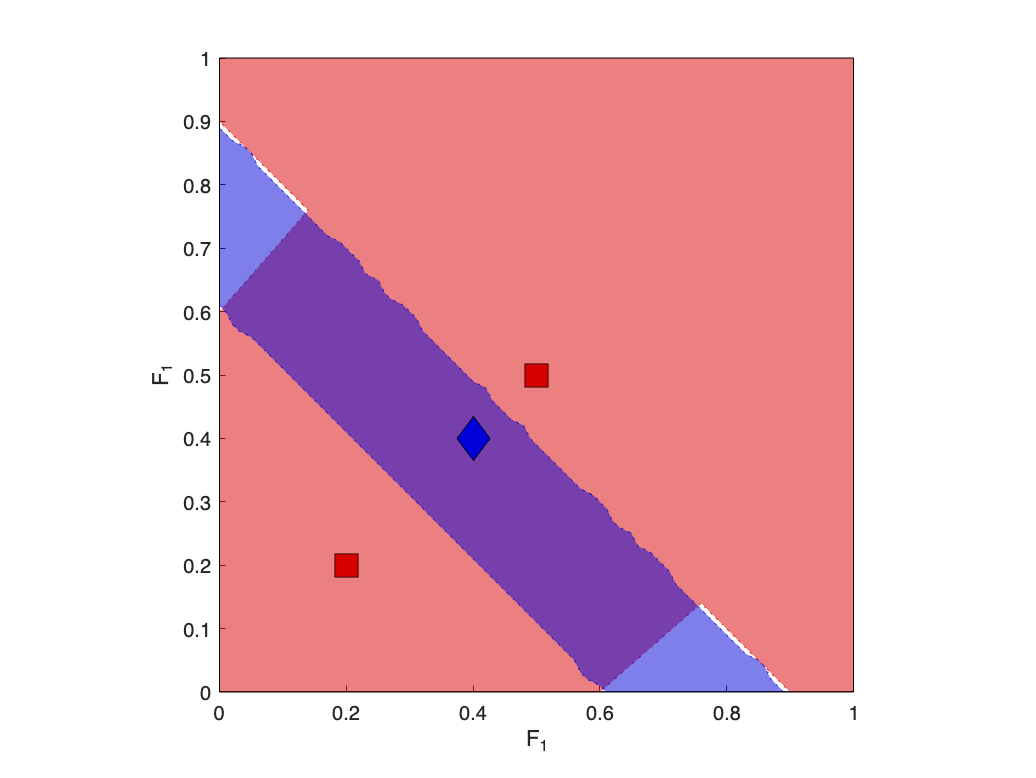

ans =     0.9580    0.2132


FM_SHH2.plotZones(0:0.01:1,1,[1 1],1)

%saving variables
save('FM_Exp2_Results','Results')
save('FM_HH1_multi.mat','FM_HH1_multi')
save('FM_HH2_multi.mat','FM_HH2_multi')
save('FM_SHH2.mat','FM_SHH2')
save('FM_HH2','FM_HH2')